# Terzaghi problem

cd(strcat(gres_root,'/Tutorial/02_terzaghi'))
terzaghi_root = fullfile(gres_root,'Tests','Terzaghi_Biot');

In this tutorial, we will build fully coupled model implementing the Terzaghi problem.

Terzaghi problem is a standard benchmark for the Biot equations, which couple a Single phase flow model with a mechanical model. 

## Governing equations

$$div(\mathbf{\bar{\sigma'}}) - \alpha \nabla p = -\mathbf{F}$$                    Balance of linear momentum in Porous media

$$    div\bigg( \frac{\mathbf{\bar K}}{\mu} \nabla p \bigg) - \alpha \frac{\partial \epsilon}{\partial t} - \phi \beta \frac{\partial p}{\partial t} = q$$  Mass conservation of slightly compressible fully saturated fluid

Where:

 $$\mathbf{\bar{\sigma'}}$$ is the effective stress;

$p$ is the pore pressure;

$\mathbf{F}$ represents body forces (such as gravity);

$\alpha$ is the Biot coefficient;

$\phi \;$ is the porosity

$\beta \;$is the fluid compressibility

$\mathbf{\bar K}$  is the intrinsic permeability tensor;

$\mu$ is the dynamic viscosity;

$q$  is an external source term.

The following boundary conditions can be prescribed


$$  $$
\begin{cases}
    \mathbf{u}(\mathbf{x},t) = \mathbf{u}_D(\mathbf{x},t) 
    & \text{on } \, \Gamma_D:\ \text{prescribed displacements} \\[6pt]

    \bar{\mathbf{\sigma}}(\mathbf{x},t) \cdot \mathbf{n}(\mathbf{x}) = \mathbf{t}_N(\mathbf{x},t) 
    & \text{on }  \,\Gamma_N:\ \text{surface forces} \\[6pt]

    p(\mathbf{x},t) = p_D(\mathbf{x},t) 
    & \text{on } \,  \Gamma_p:\ \text{prescribed pressure} \\[6pt]

    \mathbf{q}(\mathbf{x},t) \cdot \mathbf{n}(\mathbf{x}) = q_N(\mathbf{x},t) 
    & \text{on } \, \Gamma_q:\ \text{prescribed flux}
\end{cases}
$$
$$


The primary variable of the problem are the solid displacements and the fluid pressures.

For the details on the above equations see Castelletto,2015.

## Problem setting

We simulate the consolidation of a poroelastic fluid-saturated column of height $H$ having unit cross-section. The column is instantaneously loaded at time  = 0 s with a constant compressive traction  $p_T$ applied on the top face as shown in the figure below. Only the loaded face is permeable to fluid flow, with the remaining parts of the boundary subject to roller constraints and impervious.

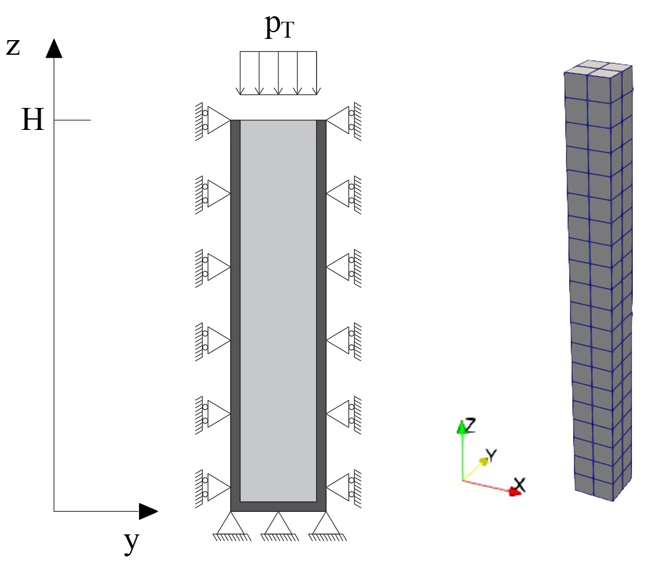

The analytical solutions can be found in Castelletto,2015

## Model setup

The first step is the definition of the parameters of the simulation creating an object of the class` SimulationParameters, `which requires a .xml file as input. 

simParam = SimulationParameters(fullfile(terzaghi_root,"Inputs",'simparam.xml'));

simParam

A `SimulationParameters `object stores general parameters controlling the time step and the non linear solver. 

We then import the mesh from a `.msh` file, as expained in the [previous tutorial](matlab:open('..\01_meshInput\meshIO.mlx')).

topology = Mesh();

simParam =   SimulationParameters with properties:

            itMaxNR: 10
             relTol: 1.0000e-08
             absTol: 1.0000e-09
              pNorm: 2
              theta: 1
              dtIni: 0.5000
              dtMin: 0.5000
              dtMax: 5
               tIni: 0
               tMax: 180
            multFac: 1.1000
             divFac: 2
            pTarget: []
            sTarget: 0.4000
           NLSolver: 'Newton'
          verbosity: 2
       goOnBackstep: 0
    isTimeDependent: 1


fileName = fullfile(terzaghi_root,"Inputs",'Mesh','Column_hexa.msh');
topology.importMesh(fileName);

To initialize the Finite Elements kernels in our model, we need to create an instance of the `Elements` class. We need to specify the order of integration, that is the number of Gauss points in each direction. Since the mesh consists of 8 nodes Hexahedra, we need 2 GP for exact integration.

gaussOrder = 2;
elems = Elements(topology,gaussOrder)

To define the Materials

mat = Materials(fullfile(terzaghi_root,"Input",'materials.xml'));

we need to input a xml file containing two types of blocks, one for solids and one for fluids

Declaring the material, the solid part of the domain may be partitioned into multiple regions consisting of different materials.  When you declare a new material, you must specify the regions it belongs to using the **CellTag.**

In the <Solid cellTags = "XXX"> we specify all the properties associated with the rock: the `<Constitutive>` block holds the parameters of the specific constitutive model,  while the` <PorousRock> `block contains the porosity, the rock compressibility, the specific weight and the intrinsic permeabillity.

The **fluid** is always defined for the **entire domain**, thus requiring only **one block** with its properties. **If more the one block are specified for a fluid material, GReS will throw an error.**  This block `holds `the specific weight of the fluid (here assumed to be 0), the fluid compressibility, and the dynamic viscosity`.`

**The user is responsible for the dimensional consistency of all physical quantities involved in the model.**

We then create an instance of the `Faces `class, which can be seen as a Finite Volume equivalent of the Elements class.

faces = Faces(model, topology)

For following object definitions, we need to wrap the instances of `Mesh(), Elements() `and `Faces()` into a structure named `grid.`

grid = struct('topology',topology,'cells',elems,'faces',faces);

elems =   Elements with properties:

             mesh: [1×1 Mesh]
      mapVTK2elem: [29×1 double]
            elems: {[]  [1×1 Quadrilateral]  []  []  [1×1 Hexahedron]  []  []  []}
     nCellsByType: [0 80 0 0 0]
      nSurfByType: [0 168 0]
    vtk3DTypeList: [10 12 13 14 29]
    vtk2DTypeList: [5 9 28]
       nNodesElem: [3 4 9 4 8 27]


We proceed defining the details of the output of the current simulation, creating an instance of the `OutState `class.

printUtils = OutState(topology,fullfile(terzaghi_root,"Input",'output.xml'));

Here, we specify the printTimes and we request GReS to write both to VTK. and MAT. files. MAT. files can be particoularly useful to get the history of the simulation.

We then proceed defining the boundary conditions.

% Creating boundaries conditions.
bound = Boundaries(fullfile(terzaghi_root,"Inputs","boundaries.xml"),grid);

faces =   Faces with properties:

       nodes2Faces: [1296×1 double]
            mapN2F: [325×1 double]
    faces2Elements: [480×2 double]
            mapF2E: [81×1 double]
     faceNeighbors: [324×2 double]
      faceCentroid: [324×3 double]
        faceNormal: [324×3 double]
            nFaces: 324


Let us take a look at the boundary condition file:

Each boundary condition is defined by a `<BC>` block. This block contains three essential fields:

- **Identification of the Type of Boundary Condition:** Specifies the physical nature of the condition (Dirichlet, Neumann), how it's applied (nodeBC,surfBC,volume), for which physics (Poromechanics,SinglePhaseFlow).

- **Identification of where to apply in the Domain:** Specifies where in the domain to apply the condition by passing the location (Ex. surfaceTags) or by the specific entitie (number of the node, face, or etc).

- **Boundary Values:** Specifies the numerical values associated with the condition.

The following block shows the declaration of a boundary condition named “xxxx” of the Dirichlet type applied to the surfaces at the element level for the Single-Phase Flow model. This condition is applied at the top of the domain through the preselection given by “surfaceTags = 2”. This is a zero pressure condition, because we only have one <BCevent /> block with a value of 0 from the initial moment.

## Solution processing

### Discretizer class

Up to now we only define the input for our simulation. It is time to run our model.

First, we instanciate the `Discretizer `class creating an object called `domain.`

% Create object handling construction of Jacobian and rhs of the model
domain = Discretizer('ModelType',model,...
                     'SimulationParameters',simParam,...
                     'DoFManager',dofmanager,...
                     'Boundaries',bound,...
                     'OutState',printUtils,...
                     'Materials',mat,...
                     'Grid',grid)

This class wraps all the objects previously defined, and in the `solver `property stores a database with the physical solvers of the model. Another important property is `State`, which is an object storing primary variables and derived quantities of the model for a specific time instant. 

domain.state
domain.state.data

We can inspect the database using the `getSolver() `function:

poro = domain.getSolver('Poromechanics')
flow = domain.getSolver('SinglePhaseFlow')
biot = domain.getSolver("Poromechanics","SinglePhaseFlow")

domain =   Discretizer with properties:

           solver: [3×1 containers.Map]
             dofm: [1×1 DoFManager]
        simparams: [1×1 SimulationParameters]
              bcs: [1×1 Boundaries]
         outstate: [1×1 OutState]
        materials: [1×1 Materials]
      solverNames: {3×1 cell}
            model: [1×1 ModelType]
           fields: ["Poromechanics"    "SinglePhaseFlow"]
             grid: [1×1 struct]
    interfaceList: []
       interfaces: {}
    interfaceSurf: []
            state: [1×1 State]


Each physical model correspond to a class, whose properties include the associated Jacobian `J `right-hand-side  `rhs `blocks. Clearly, these properties are still empty since no computations have yet been defined. Each physical models has access to the variables stored in `state.data `to perform computations.

Before running the simulation, we are still missing the initial conditions! They are applied "manually" by directly modifying the `state `object before the simulation takes place. This means that **no input files are needed to apply the initial conditions.**

F = -10; % vertical force

ans =   State with properties:

       t: 0
    data: [1×1 struct]


applyTerzaghiIC(domain.state,mat,topology,F);

ans = struct with fields:
         conv: [1×1 struct]
         curr: [1×1 struct]
    iniStress: [640×6 double]
     dispConv: [567×1 double]
     dispCurr: [567×1 double]
     pressure: [80×1 double]


Finally, we can print the initial state of the simulation to check that the initial conditions have been correctly assigned. The function `printState() `produces all the outputs at time `state.t.`

printState(domain);

poro =   Poromechanics with properties:

              K: []
           fInt: []
    cell2stress: [80×1 double]
          field: 'Poromechanics'
              J: []
            rhs: []
          model: [1×1 ModelType]
      simParams: [1×1 SimulationParameters]
           dofm: [1×1 DoFManager]
           mesh: [1×1 Mesh]
       elements: [1×1 Elements]
          faces: [1×1 Faces]
       material: [1×1 Materials]
          state: [1×1 State]
          fldId: 1
            bcs: [1×1 Boundaries]


### Simulation loop

We are all set to run our first simulation! Single domains fully coupled simulations are implemented with the `FCSolver(); `

Solver = FCSolver(domain)

flow =   SinglePhaseFlow with properties:

         trans: [324×1 double]
    isIntFaces: [324×1 logical]
       rhsGrav: []
             H: []
             P: []
         field: 'SinglePhaseFlow'
             J: []
           rhs: []
         model: [1×1 ModelType]
     simParams: [1×1 SimulationParameters]
          dofm: [1×1 DoFManager]
          mesh: [1×1 Mesh]
      elements: [1×1 Elements]
         faces: [1×1 Faces]
      material: [1×1 Materials]
         state: [1×1 State]
         fldId: 2
           bcs: [1×1 Boundaries]


The actual simulation (i.e the time loop) is actually performed by the `NonLinearLoop()` method, here reported for reference.

At each time step, a Newton-Raphson loop solves the (possibly) non linear problem. If the problem is linear, only one linear system solution is expected to reach convergence.

[simState] = Solver.NonLinearLoop();

biot =   Biot with properties:

             Q: []
     flowModel: 'SinglePhaseFlow'
    flowScheme: 'FV'
        fields: ["Poromechanics"    "SinglePhaseFlow"]
             J: {2×1 cell}
           rhs: {2×1 cell}
         model: [1×1 ModelType]
     simParams: [1×1 SimulationParameters]
          dofm: [1×1 DoFManager]
          mesh: [1×1 Mesh]
      elements: [1×1 Elements]
         faces: [1×1 Faces]
      material: [1×1 Materials]
      GaussPts: []
         state: [1×1 State]
         fldId: [2×1 double]
           bcs: [1×1 Boundaries]


Dua to the verbosity level of `SimulationParameters`, GReS logs the residual at each Newton iteration. As expected, only one iteration is needed to converge and to move to the next time step. Notice that the initial time step

simParam.dtIni

is progressively incremented due to the multiplicative factor

simParam.multFac

and stops at

simParam.tMax

## Post processing

We can finilize our simulation and write the output.

domain.outstate.finalize();

Solver =   FCSolver with properties:

    solStatistics: [1×1 SolverStatistics]



TSTEP 1   ---  TIME 0.500000  --- DT = 5.000000e-01
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     1.961169e-05     1.000000e+00
1     2.388377e-15     1.217834e-10

TSTEP 2   ---  TIME 1.050000  --- DT = 5.500000e-01
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     1.192436e-05     1.000000e+00
1     2.606641e-15     2.185979e-10

TSTEP 3   ---  TIME 1.655000  --- DT = 6.050000e-01
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     7.490474e-06     1.000000e+00
1     2.439194e-15     3.256394e-10

TSTEP 4   ---  TIME 2.320500  --- DT = 6.655000e-01
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     4.999191e-06     1.000000e+00
1     2.824000e-15     5.648914e-10

TSTEP 5   ---  TIME 3.052550  --- DT = 7.320500e-01
---------------------------------------------------

ans = 0.5000

ans = 1.1000

ans = 180

A `.pvd `file will appear  with the same name specified in the "outFolder" option in the OutState object definition.

We can open the file using [Paraview](https://www.paraview.org/). 

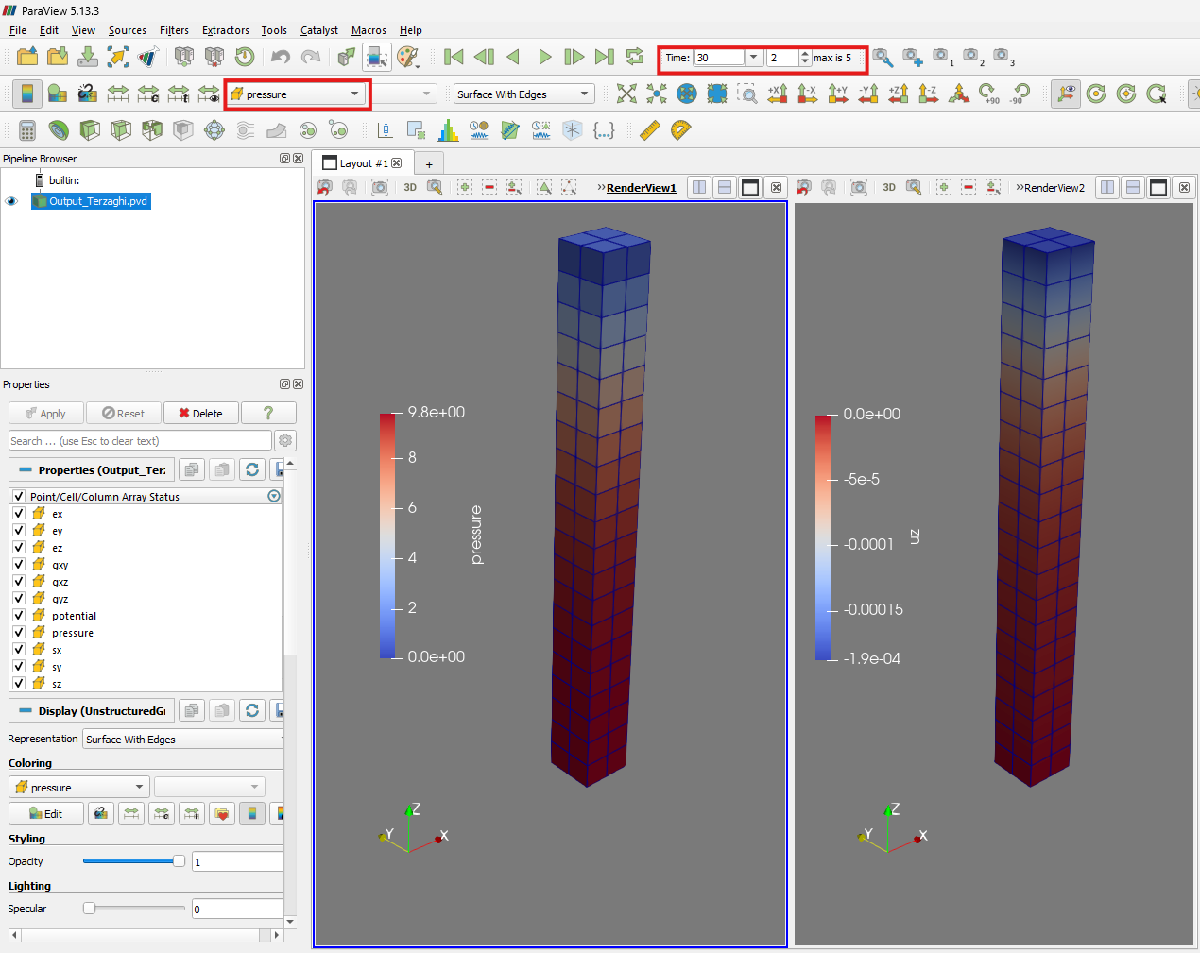

## References

*Nicola Castelletto, Joshua A White, and HA Tchelepi. Accuracy and convergence properties of the fixed-stress iterative solution of two-way coupled poromechanics. International Journal for Numerical and Analytical Methods in Geomechanics,39(14):1593–1618, 2015.*